Canny ridge filter testing

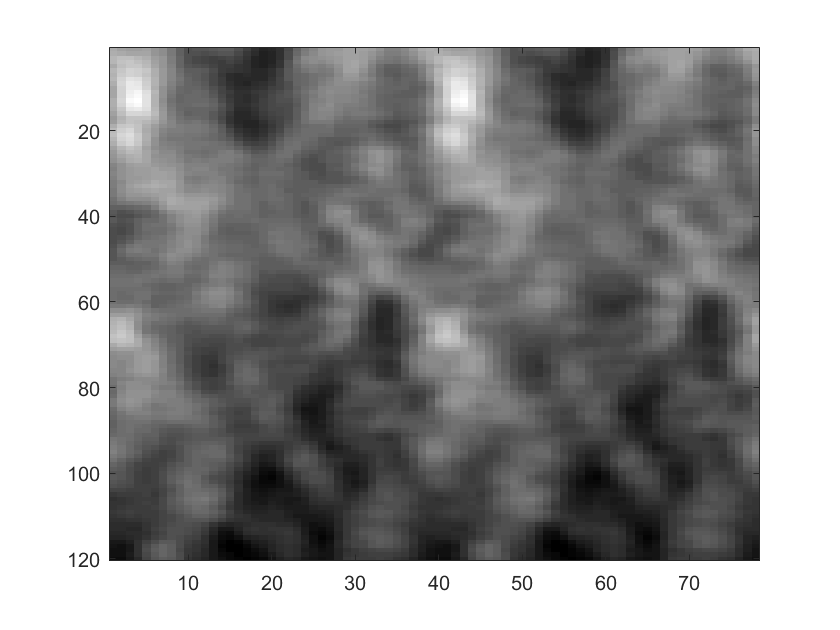

fname1 = '..\testing\testKymographs\SM1_JF-549_500ms.exp_50.Power_100x6s_3_MMStack_Pos0.ome_denoise_reg_ring15_kymoWrap.tif';
fname2 = '.\testing\testKymographs\180327_Sam1_1mW_RingHiLO_1_MMStack_Pos0.ome_denoise_reg_ring1_kymoWrap.tif';

im = imread(fname2);
im(end,:)=[];%remove the last black (non-data) row
imagesc(im);
colormap gray

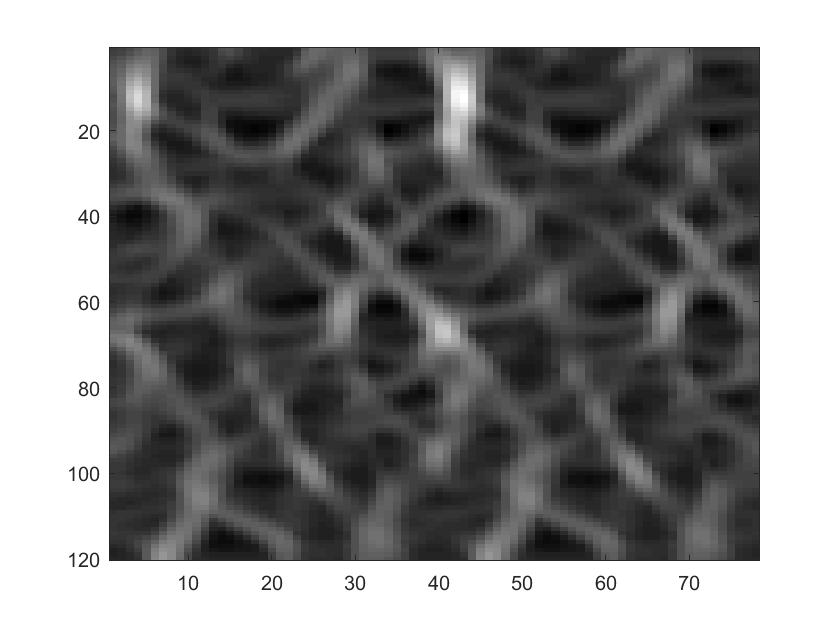


blurSigma = 2;
[ridge ridge_nms] = cannyridgefilter(im,blurSigma);
imagesc(ridge);
colormap gray;

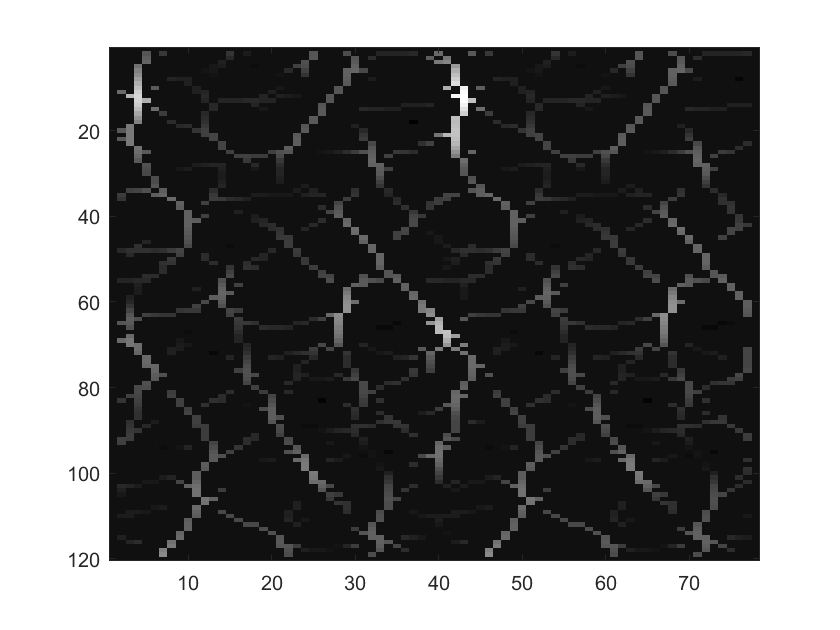

imagesc(ridge_nms);
colormap gray;

looks pretty good

What if we try 45 degrees too?